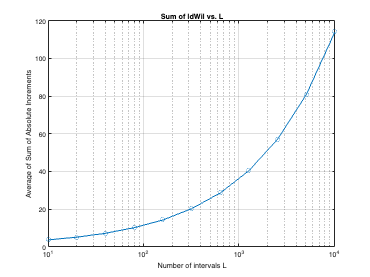

% Number of simulations to average over
numSimulations = 1000;

% Array to hold values of L
L_values = [10, 20, 40, 80, 160, 320, 640, 1280, 2560, 5120, 10240];

% Array to store results
sumAbsIncrements = zeros(size(L_values));

% Loop over different values of L
for j = 1:length(L_values)
    L = L_values(j);
    dt = 2 / L;  % delta t
    
    % Temporary array to store the sum of absolute increments for each simulation
    tempSum = zeros(1, numSimulations);
    
    % Perform simulations
    for i = 1:numSimulations
        % Generate Wiener increments
        dW = sqrt(dt) * randn(1, L);
        
        % Compute the sum of absolute increments
        tempSum(i) = sum(abs(dW));
    end
    
    % Compute the average of the sum of absolute increments
    sumAbsIncrements(j) = mean(tempSum);
end

% Plotting the results
figure;
plot(L_values, sumAbsIncrements, 'o-');
xlabel('Number of intervals L');
ylabel('Average of Sum of Absolute Increments');
title('Sum of |dWi| vs. L');
set(gca, 'XScale', 'log');
grid on;